# Section 12: Debugging with conditional breakpoints

## An example case 

rng("default")
data = rand(1, 1000)-0.1;
for val = data
    my_val = realsqrt(val); % only positive values allowed
end

Realsqrt produced complex result.

## Using normal breakpoint would trigger every iteration of the for loop

% hit ctrl+enter to run section, f5 to continue. We will trigger the breakpoint many times before the error is thrown
data = rand(1, 1000)-0.1;
for val = data
    my_val = realsqrt(val); % only positive values allowed
end

## Using conditional breakpoint

% hit ctrl+enter to run section. 
% Condition is checked everytime we arrive at the breakpoint (introducing some overhead), but will stop the program when a negative value is found 
data = rand(1, 1000)-0.1;
for val = data
    my_val = realsqrt(val); % only positive values allowed
end

Right click on the line 15 and you can set the conditional breakpoint like highlighted in the images below

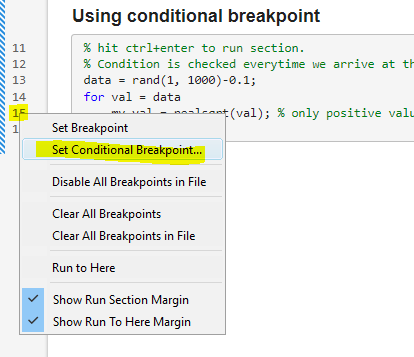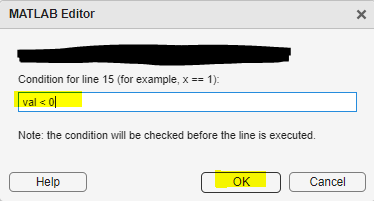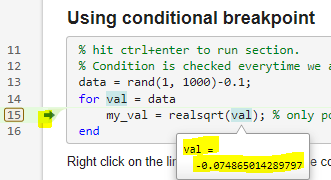

## Using dbstop to stop at certain errors

% select whole cell and run with F9 (section run will not trigger the dbstop as intented)
dbstop if error MATLAB:realsqrt:complexResult
data = rand(1, 1000)-0.1;
realsqrt_each_element(data)